### ABV Impact Energy Analysis (FEA boundary conditions)

% ASSUMPTIONS / INPUTS TO VERIFY

clear; clc; close all;

% ABV mass (same as achievability_analysis.mlx)
m_abv = 12.7;                        % kg
m_payload = linspace(0, 10, 21);     % kg, mechanism mass sweep
m_total = m_abv + m_payload;


% Velocities
v_min = 0.05; v_max = 0.10;          % m/s, SYS.10
v_fault = 0.15;                      % m/s, overspeed fault case (50% over v_max)
v_sweep = linspace(0.02, 0.30, 57);  % m/s

% Probe tip geometry
R_tip = 0.010;                       % m, hemispherical tip radius (VERIFY from CAD)

% Structural compliance behind the contact
k_struct = 1e6;                      % N/m, nominal (VERIFY from FEA / push test)
k_sweep  = [1e4 1e5 1e6 1e7 Inf];    % N/m, Inf = contact-only upper bound

% Materials: name, E (Pa), nu, Sy (Pa)
print_knockdown = 0.70;              % printed PETG strength factor (VERIFY)
mat_name = {'Al 6061-T6', 'Delrin (acetal)', 'PETG (printed)'};
mat_E    = [68.9e9, 3.1e9, 2.0e9];
mat_nu   = [0.33,   0.35,  0.38];
mat_Sy   = [276e6,  72e6,  50e6*print_knockdown];
nMat = numel(mat_name);
yield_factor = 1.6;

r_mech_mount = 0.5625 * 0.3048;                   % m, mechanism CG at front edge (VERIFY)
m_ground = (1.695 * 9.81 * 26*0.0254) / (9.81 * r_mech_mount);   % kg
mass_report = [0 round(m_ground,1) 10];           % replaces [0 4 10]

### Kinetic energy

KE_vmax  = 0.5 * m_total * v_max^2;    % J
KE_fault = 0.5 * m_total * v_fault^2;  % J
fprintf('\n KINETIC ENERGY AT CONTACT \n');


 KINETIC ENERGY AT CONTACT 


fprintf('%8s %10s %12s %14s\n', 'm_pay', 'm_tot', 'KE@vmax (J)', 'KE@fault (J)');

   m_pay      m_tot  KE@vmax (J)   KE@fault (J)


for mr = mass_report
    [~, i] = min(abs(m_payload - mr));
    fprintf('%8.1f %10.1f %12.4f %14.4f\n', m_payload(i), m_total(i), KE_vmax(i), KE_fault(i));
end

     0.0       12.7       0.0635         0.1429
     6.5       19.2       0.0960         0.2160
    10.0       22.7       0.1135         0.2554


### The three material cases

i10 = numel(m_payload);
vcases = [v_max v_fault];
F_nom = zeros(nMat,2); a_nom = zeros(nMat,2); marg_nom = zeros(nMat,2); F_ub = zeros(nMat,2);
fprintf('\n SAME-MATERIAL CASES (10 kg, R_tip = %.0f mm, k_struct = %.0e N/m) \n', R_tip*1e3, k_struct);


 SAME-MATERIAL CASES (10 kg, R_tip = 10 mm, k_struct = 1e+06 N/m) 


fprintf('%-17s %6s %9s %8s %8s %9s %7s %8s %9s %12s\n', 'Material', 'v', 'F_max', 'dent', 'a', 'p0', 'margin', 't_c', 'v_yield', 'F rigid');

Material               v     F_max     dent        a        p0  margin      t_c   v_yield      F rigid


fprintf('%-17s %6s %9s %8s %8s %9s %7s %8s %9s %12s\n', '', '(m/s)', '(N)', '(um)', '(mm)', '(MPa)', '(-)', '(ms)', '(m/s)', '(N)');

                   (m/s)       (N)     (um)     (mm)     (MPa)     (-)     (ms)     (m/s)          (N)


for k = 1:nMat
    for j = 1:2
        r  = hertz_impact(m_total(i10), vcases(j), R_tip, mat_E(k), mat_nu(k), mat_Sy(k), mat_E(k), mat_nu(k), mat_Sy(k), yield_factor, k_struct);
        ru = hertz_impact(m_total(i10), vcases(j), R_tip, mat_E(k), mat_nu(k), mat_Sy(k), mat_E(k), mat_nu(k), mat_Sy(k), yield_factor, Inf);
        vy = yield_velocity(m_total(i10), R_tip, mat_E(k), mat_nu(k), mat_Sy(k), mat_E(k), mat_nu(k), mat_Sy(k), yield_factor, k_struct);
        F_nom(k,j) = r.F; a_nom(k,j) = r.a; marg_nom(k,j) = r.margin; F_ub(k,j) = ru.F;
        fprintf('%-17s %6.2f %9.1f %8.2f %8.3f %9.1f %7.2f %8.2f %9.3f %12.1f\n', mat_name{k}, vcases(j), ...
            r.F, r.deltaH*1e6, r.a*1e3, r.p0/1e6, r.margin, r.t_c*1e3, vy, ru.F);
    end
end

Al 6061-T6          0.10     468.4    20.21    0.450    1106.5    0.40    14.66     0.007       3602.8
Al 6061-T6          0.15     704.1    26.52    0.515    1267.5    0.35    14.61     0.007       5860.7
Delrin (acetal)     0.10     421.1   147.32    1.214     136.5    0.84    17.05     0.061       1048.5
Delrin (acetal)     0.15     640.9   194.92    1.396     157.0    0.73    16.72     0.061       1705.6
PETG (printed)      0.10     406.6   189.53    1.377     102.4    0.55    17.88     0.018        888.9
PETG (printed)      0.15     621.2   251.39    1.586     118.0    0.47    17.45     0.018       1445.9


fprintf('margin = %.1f*Sy/p0 (>1 = stays elastic). dent = Hertz approach at the contact.\n', yield_factor);

margin = 1.6*Sy/p0 (>1 = stays elastic). dent = Hertz approach at the contact.


% Mixed pairs: probe material (rows) x drogue material (columns), 10 kg @ v_max
fprintf('\n MIXED PAIRS (10 kg, v_max, k_struct = %.0e N/m): F_max N | margin (weaker part) \n', k_struct);


 MIXED PAIRS (10 kg, v_max, k_struct = 1e+06 N/m): F_max N | margin (weaker part) 


fprintf('%-17s', 'probe \ drogue');

probe \ drogue   

for d = 1:nMat, fprintf(' %24s', mat_name{d}); end

               Al 6061-T6          Delrin (acetal)           PETG (printed)

fprintf('\n');
for p = 1:nMat
    fprintf('%-17s', mat_name{p});
    for d = 1:nMat
        r = hertz_impact(m_total(i10), v_max, R_tip, mat_E(p), mat_nu(p), mat_Sy(p), mat_E(d), mat_nu(d), mat_Sy(d), yield_factor, k_struct);
        if r.margin_probe <= r.margin_drogue, w = 'probe'; else, w = 'drogue'; end
        fprintf(' %24s', sprintf('%6.1f | %5.2f (%s)', r.F, r.margin, w));
    end
    fprintf('\n');
end

Al 6061-T6       

    468.4 |  0.40 (probe)   438.8 |  0.54 (drogue)   428.6 |  0.35 (drogue)

Delrin (acetal)  

    438.8 |  0.54 (probe)    421.1 |  0.84 (probe)   413.5 |  0.48 (drogue)

PETG (printed)   

    428.6 |  0.35 (probe)    413.5 |  0.48 (probe)    406.6 |  0.55 (probe)

### How stiff can the structure be?

fprintf('\n STRUCTURAL STIFFNESS SENSITIVITY (10 kg, v_max): F_max N | margin \n');


 STRUCTURAL STIFFNESS SENSITIVITY (10 kg, v_max): F_max N | margin 


fprintf('%-17s', 'Material');

Material         

for q = 1:numel(k_sweep), fprintf(' %17s', sprintf('k = %.0e', k_sweep(q))); end

         k = 1e+04         k = 1e+05         k = 1e+06         k = 1e+07           k = Inf

fprintf('\n');
F_k = zeros(nMat, numel(k_sweep));
for k = 1:nMat
    fprintf('%-17s', mat_name{k});
    for q = 1:numel(k_sweep)
        r = hertz_impact(m_total(i10), v_max, R_tip, mat_E(k), mat_nu(k), mat_Sy(k), mat_E(k), mat_nu(k), mat_Sy(k), yield_factor, k_sweep(q));
        F_k(k,q) = r.F;
        fprintf(' %17s', sprintf('%7.1f | %5.2f', r.F, r.margin));
    end
    fprintf('\n');
end

Al 6061-T6       

      47.6 |  0.86     150.3 |  0.58     468.4 |  0.40    1351.7 |  0.28    3602.8 |  0.20

Delrin (acetal)  

      47.5 |  1.75     147.8 |  1.20     421.1 |  0.84     839.1 |  0.67    1048.5 |  0.62

PETG (printed)   

      47.5 |  1.12     146.9 |  0.77     406.6 |  0.55     749.5 |  0.45     888.9 |  0.42


k_allow = zeros(1, nMat);
fprintf('\nStiffest allowable k_struct for an elastic contact at v_fault = %.2f m/s, 10 kg:\n', v_fault);


Stiffest allowable k_struct for an elastic contact at v_fault = 0.15 m/s, 10 kg:


for k = 1:nMat
    k_allow(k) = max_stiffness(m_total(i10), v_fault, R_tip, mat_E(k), mat_nu(k), mat_Sy(k), yield_factor);
    if isinf(k_allow(k))
        fprintf('  %-17s any stiffness (contact-only case is already elastic)\n', mat_name{k});
    else
        fprintf('  %-17s %.2e N/m  -> peak force %.0f N\n', mat_name{k}, k_allow(k), ...
            hertz_impact(m_total(i10), v_fault, R_tip, mat_E(k), mat_nu(k), mat_Sy(k), mat_E(k), mat_nu(k), mat_Sy(k), yield_factor, k_allow(k)).F);
    end
end

  Al 6061-T6        1.74e+03 N/m  -> peak force 30 N
  Delrin (acetal)   1.31e+05 N/m  -> peak force 253 N
  PETG (printed)    8.69e+03 N/m  -> peak force 66 N


### Loads to apply in the static FEA (item 1)

fprintf('\n FEA LOAD CASES (10 kg payload, k_struct = %.0e N/m) \n', k_struct);


 FEA LOAD CASES (10 kg payload, k_struct = 1e+06 N/m) 


fprintf('Apply F_max at the probe tip over a circle of radius a; react it through the\n');

Apply F_max at the probe tip over a circle of radius a; react it through the


fprintf('mechanism mount. Peak subsurface shear is ~0.48a below the surface.\n');

mechanism mount. Peak subsurface shear is ~0.48a below the surface.


fprintf('%-17s %18s %18s %20s\n', 'Material', 'Nominal (v_max)', 'Fault (v_fault)', 'Rigid upper bound');

Material             Nominal (v_max)    Fault (v_fault)    Rigid upper bound


for k = 1:nMat
    fprintf('%-17s %11.1f N    %11.1f N    %13.1f N\n', mat_name{k}, F_nom(k,1), F_nom(k,2), F_ub(k,2));
end

Al 6061-T6              468.4 N          704.1 N           5860.7 N
Delrin (acetal)         421.1 N          640.9 N           1705.6 N
PETG (printed)          406.6 N          621.2 N           1445.9 N


fprintf(['Iterate: run the FEA with these loads, read tip deflection, set\n' ...
         'k_struct = F / deflection, and rerun this script until it settles.\n']);

Iterate: run the FEA with these loads, read tip deflection, set
k_struct = F / deflection, and rerun this script until it settles.


r = hertz_impact(m_total(i10), v_max, R_tip, mat_E(1), mat_nu(1), mat_Sy(1), mat_E(1), mat_nu(1), mat_Sy(1), yield_factor, k_struct);
fprintf(['Contact lasts ~%.0f ms. Static FEA is valid if the mount''s first natural\n' ...
         'frequency is above ~%.0f Hz (3x the contact rate); otherwise use a dynamic\n' ...
         'amplification factor of 2 on these loads.\n'], r.t_c*1e3, 3/r.t_c);

Contact lasts ~15 ms. Static FEA is valid if the mount's first natural
frequency is above ~205 Hz (3x the contact rate); otherwise use a dynamic
amplification factor of 2 on these loads.


### Sweeps for plots

F_m = zeros(nMat, numel(m_payload)); marg_v = zeros(nMat, numel(v_sweep));
for k = 1:nMat
    for i = 1:numel(m_payload)
        F_m(k,i) = hertz_impact(m_total(i), v_max, R_tip, mat_E(k), mat_nu(k), mat_Sy(k), mat_E(k), mat_nu(k), mat_Sy(k), yield_factor, k_struct).F;
    end
    for j = 1:numel(v_sweep)
        marg_v(k,j) = hertz_impact(m_total(i10), v_sweep(j), R_tip, mat_E(k), mat_nu(k), mat_Sy(k), mat_E(k), mat_nu(k), mat_Sy(k), yield_factor, k_struct).margin;
    end
end
k_fine = logspace(3, 8, 41); F_kf = zeros(nMat, numel(k_fine)); marg_kf = zeros(nMat, numel(k_fine));
for k = 1:nMat
    for q = 1:numel(k_fine)
        r = hertz_impact(m_total(i10), v_max, R_tip, mat_E(k), mat_nu(k), mat_Sy(k), mat_E(k), mat_nu(k), mat_Sy(k), yield_factor, k_fine(q));
        F_kf(k,q) = r.F; marg_kf(k,q) = r.margin;
    end
end

### Plots

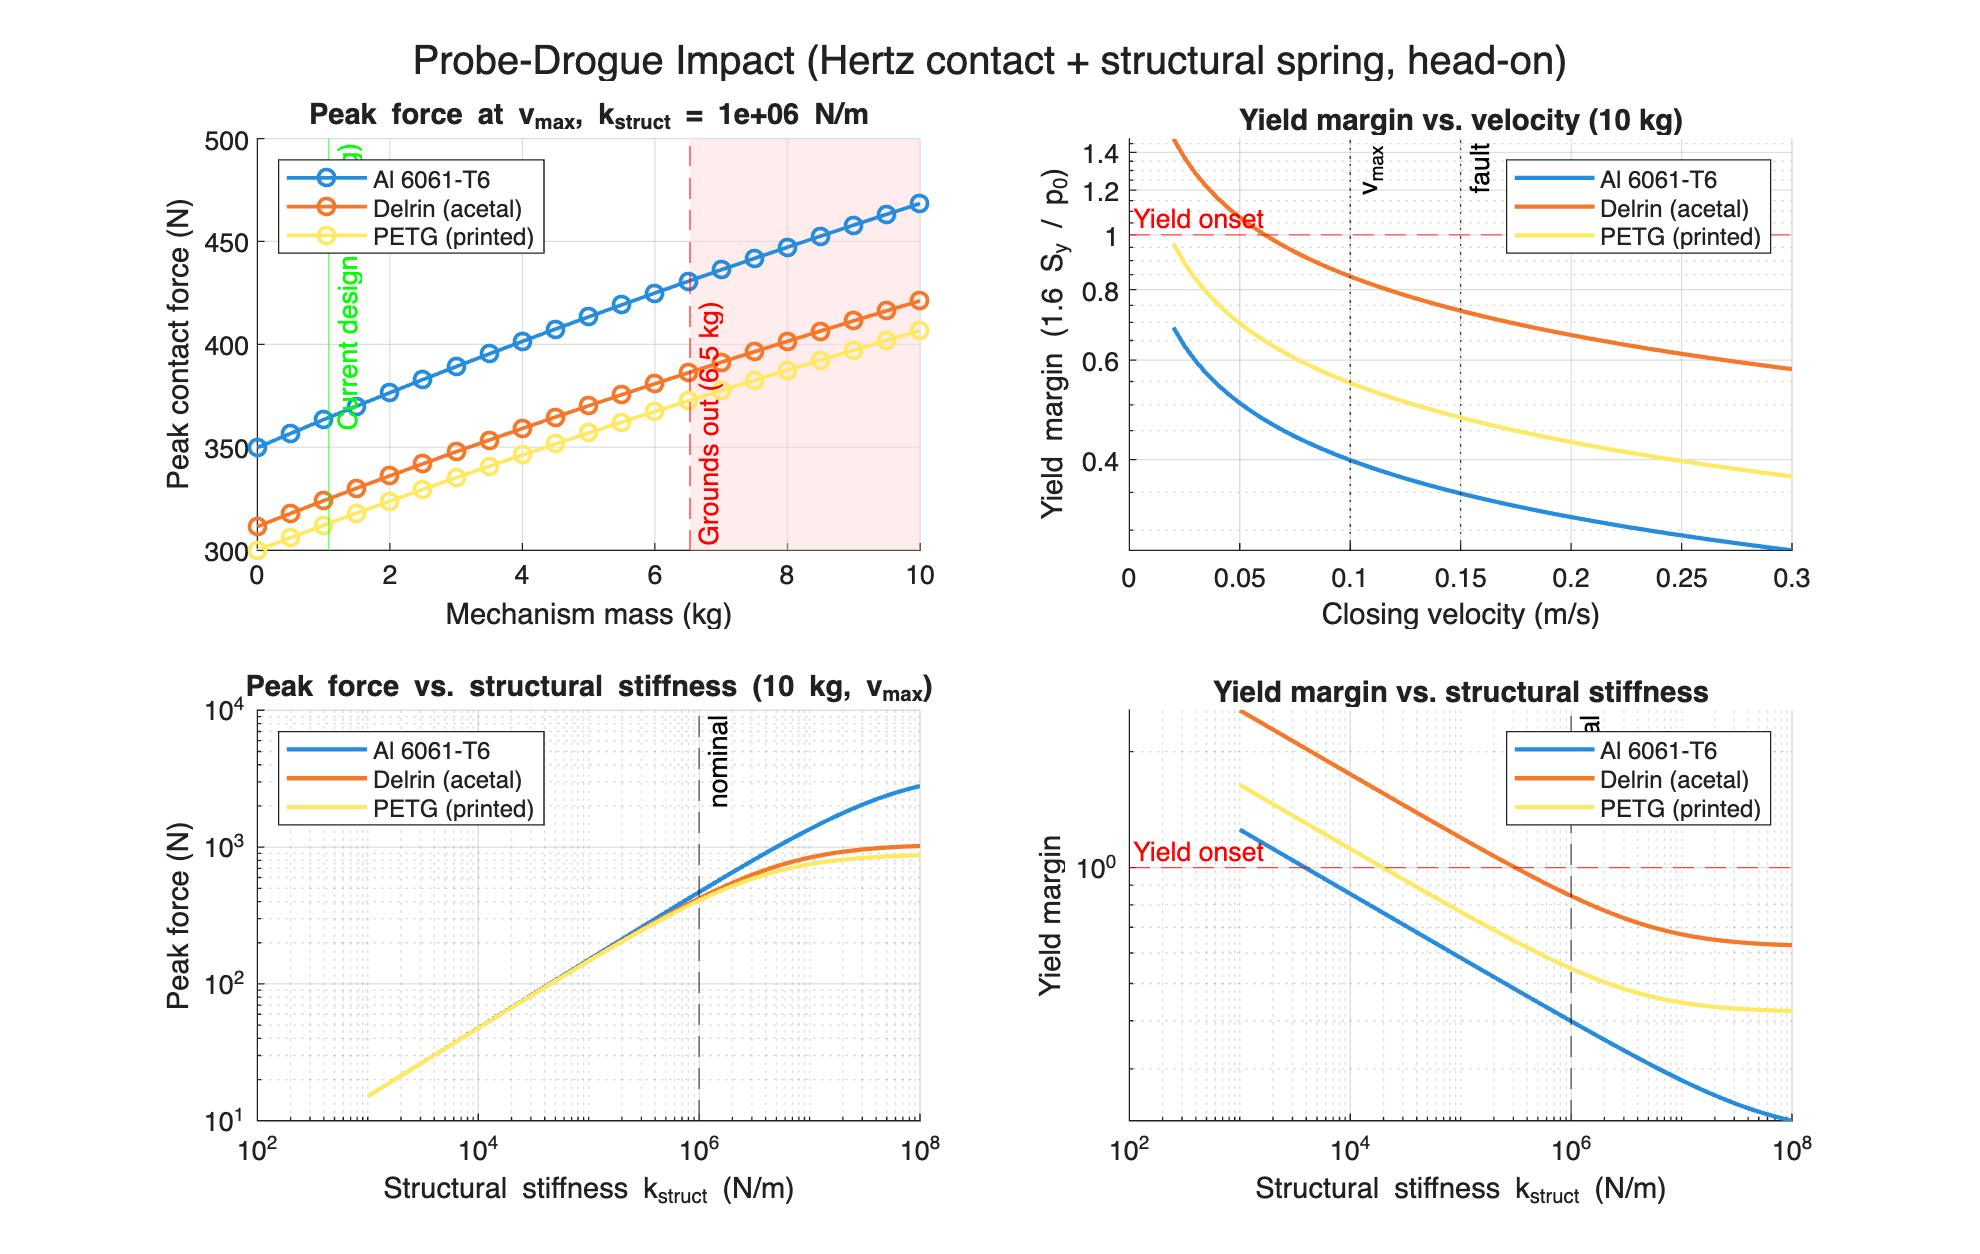

cols = lines(nMat);
figure('Name', 'Impact Energy', 'Position', [80 80 1200 760]);
theme(gcf, 'light');

subplot(2,2,1); hold on;
for k = 1:nMat, plot(m_payload, F_m(k,:), '-o', 'Color', cols(k,:), 'LineWidth', 1.4); end
xlabel('Mechanism mass (kg)'); ylabel('Peak contact force (N)');
title(sprintf('Peak force at v_{max}, k_{struct} = %.0e N/m', k_struct));
legend(mat_name, 'Location', 'northwest'); grid on;
mark_ground_limit(m_ground);
xline(1.08, 'g-', 'Current design (1.08 kg)', 'HandleVisibility', 'off');

subplot(2,2,2); hold on;
for k = 1:nMat, plot(v_sweep, marg_v(k,:), '-', 'Color', cols(k,:), 'LineWidth', 1.6); end
yline(1, 'r--', 'Yield onset', 'LabelHorizontalAlignment', 'left'); xline(v_max, 'k:', 'v_{max}'); xline(v_fault, 'k:', 'fault');
set(gca, 'YScale', 'log');
xlabel('Closing velocity (m/s)'); ylabel('Yield margin (1.6 S_y / p_0)');
title('Yield margin vs. velocity (10 kg)'); legend(mat_name, 'Location', 'northeast'); grid on;

subplot(2,2,3); hold on;
for k = 1:nMat, loglog(k_fine, F_kf(k,:), '-', 'Color', cols(k,:), 'LineWidth', 1.6); end
set(gca, 'XScale', 'log', 'YScale', 'log'); xline(k_struct, 'k--', 'nominal');
xlabel('Structural stiffness k_{struct} (N/m)'); ylabel('Peak force (N)');
title('Peak force vs. structural stiffness (10 kg, v_{max})'); legend(mat_name, 'Location', 'northwest'); grid on;

subplot(2,2,4); hold on;
for k = 1:nMat, plot(k_fine, marg_kf(k,:), '-', 'Color', cols(k,:), 'LineWidth', 1.6); end
set(gca, 'XScale', 'log', 'YScale', 'log'); yline(1, 'r--', 'Yield onset', 'LabelHorizontalAlignment', 'left'); xline(k_struct, 'k--', 'nominal');
xlabel('Structural stiffness k_{struct} (N/m)'); ylabel('Yield margin');
title('Yield margin vs. structural stiffness'); legend(mat_name, 'Location', 'northeast'); grid on;

sgtitle('Probe-Drogue Impact (Hertz contact + structural spring, head-on)');

### Local functions

function r = hertz_impact(m, v, R, E1, nu1, Sy1, E2, nu2, Sy2, yf, k_s)
% Sphere (radius R, body 1) on flat (body 2), Hertz contact in series with a
% linear spring k_s (Inf = rigid). Peak force from energy balance:
%   0.5*m*v^2 = (2/5)*F*dH(F) + F^2/(2*k_s),  dH(F) = (3F/(4*E*sqrt(R)))^(2/3)
Estar = 1 / ((1-nu1^2)/E1 + (1-nu2^2)/E2);
KE = 0.5*m*v^2;
dH = @(F) (3*F/(4*Estar*sqrt(R)))^(2/3);
if isinf(k_s)
    energy = @(F) 0.4*F*dH(F);
else
    energy = @(F) 0.4*F*dH(F) + F^2/(2*k_s);
end
lo = 0; hi = 1;
while energy(hi) < KE, hi = 2*hi; end
for it = 1:200                        % bisection (energy is monotonic in F)
    mid = 0.5*(lo + hi);
    if energy(mid) < KE, lo = mid; else, hi = mid; end
end
r.F = 0.5*(lo + hi);
r.deltaH = dH(r.F);                               % m, contact approach (dent)
if isinf(k_s), x_tot = r.deltaH; else, x_tot = r.deltaH + r.F/k_s; end
r.a  = sqrt(R*r.deltaH);                          % m, contact radius
r.p0 = 3*r.F / (2*pi*r.a^2);                      % Pa, peak contact pressure
r.t_c = 3 * x_tot / v;                            % s, contact duration (approx.)
r.margin_probe  = yf*Sy1 / r.p0;
r.margin_drogue = yf*Sy2 / r.p0;
r.margin = min(r.margin_probe, r.margin_drogue);
end

function vy = yield_velocity(m, R, E1, nu1, Sy1, E2, nu2, Sy2, yf, k_s)
% Closing velocity at which the contact first yields (margin = 1).
lo = 1e-5; hi = 10;
if hertz_impact(m, hi, R, E1, nu1, Sy1, E2, nu2, Sy2, yf, k_s).margin > 1, vy = Inf; return; end
for it = 1:100
    mid = sqrt(lo*hi);
    if hertz_impact(m, mid, R, E1, nu1, Sy1, E2, nu2, Sy2, yf, k_s).margin > 1, lo = mid; else, hi = mid; end
end
vy = sqrt(lo*hi);
end

function k_max = max_stiffness(m, v, R, E, nu, Sy, yf)
% Stiffest series spring that keeps a same-material contact elastic.
if hertz_impact(m, v, R, E, nu, Sy, E, nu, Sy, yf, Inf).margin >= 1, k_max = Inf; return; end
lo = 1; hi = 1e12;
for it = 1:100
    mid = sqrt(lo*hi);
    if hertz_impact(m, v, R, E, nu, Sy, E, nu, Sy, yf, mid).margin >= 1, lo = mid; else, hi = mid; end
end
k_max = lo;
end

function mark_ground_limit(m_lim)
% Shade payload masses past the grounding limit on the current axes.
xl = xlim; yl = ylim;
if m_lim < xl(2)
    hold on;
    h = patch([m_lim xl(2) xl(2) m_lim], [yl(1) yl(1) yl(2) yl(2)], [1 0.85 0.85], ...
        'EdgeColor', 'none', 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
    uistack(h, 'bottom');
    xline(m_lim, 'r--', sprintf('Grounds out (%.1f kg)', m_lim), ...
        'HandleVisibility', 'off', 'LabelVerticalAlignment', 'bottom');
    xlim(xl); ylim(yl);
end
end